Sampling parameters

Fs=1000;  %Sampling frequency (Hz)
T=1;      %Time period
t=0:1/Fs:T-1/Fs;

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


f1=50;
f2=100;
x1=sin(2*pi*f1*t);

x1 =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


x2=sin(2*pi*f2*t);

x2 =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878


New signal

x=x1+x2;

x =          0    0.8968    1.5388    1.7601    1.5388    1.0000    0.3633   -0.1420   -0.3633   -0.2788   -0.0000    0.2788    0.3633    0.1420   -0.3633   -1.0000   -1.5388   -1.7601   -1.5388   -0.8968   -0.0000    0.8968    1.5388    1.7601    1.5388    1.0000    0.3633   -0.1420   -0.3633   -0.2788   -0.0000    0.2788    0.3633    0.1420   -0.3633   -1.0000   -1.5388   -1.7601   -1.5388   -0.8968   -0.0000    0.8968    1.5388    1.7601    1.5388    1.0000    0.3633   -0.1420   -0.3633   -0.2788


Plot the individual and combined signals

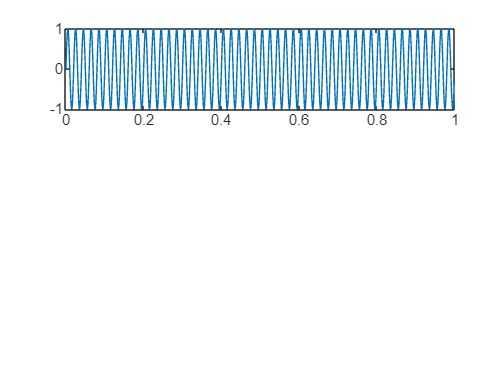

figure;
subplot(3,1,1)
plot(t,x1)

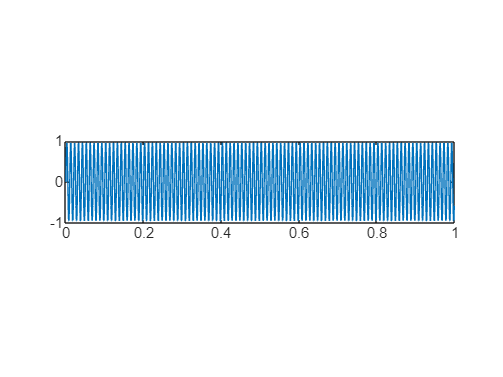

subplot(3,1,2)
plot(t,x2)

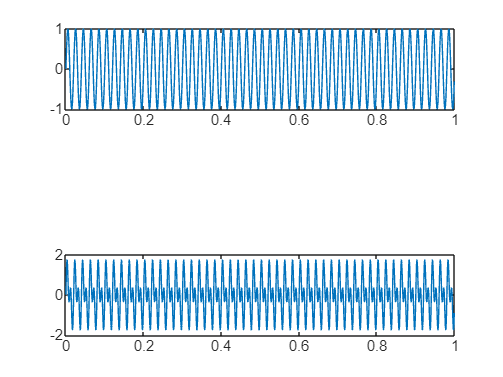

subplot(3,1,3)
plot(t,x)

Compute and plot the frequency spectrum

N=length(x)

N = 1000

X=fft(x)         %FFT of combined signal

X = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i


X_mag=abs(X)/N   %Normalize magnitude

X_mag =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:N-1)*(Fs/N) %Frequency vector

f =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


half=floor(N/2)